## Tarea 7 extra 

# Stephanie Leitón B74106

Código de basa en las siguientes documentaciones:

# Augmented Reality Using AprilTag Markers

[https://la.mathworks.com/help/vision/ug/augmented-reality-using-apriltag-markers.html](https://la.mathworks.com/help/vision/ug/augmented-reality-using-apriltag-markers.html) 

# Prepare Camera and Capture Images For Camera Calibration

[https://la.mathworks.com/help/vision/ug/prepare-camera-and-capture-images-for-camera-calibration.html](https://la.mathworks.com/help/vision/ug/prepare-camera-and-capture-images-for-camera-calibration.html) 

# Camera Calibrator

[https://la.mathworks.com/help/vision/ref/cameracalibrator-app.html](https://la.mathworks.com/help/vision/ref/cameracalibrator-app.html) 

### Sección 1

Pruebas de calibración de la camara del celular

Para esta prueba se calobró y probó con tomas de las imágenes en la pantalla de la computadora tomadas desde el celular

Este código fue brindado por la aplicación de calibración de matlab

% Auto-generated by cameraCalibrator app on 08-Dec-2024
%-------------------------------------------------------

% Define images to process
imageFileNames = {'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231524024_HDR.jpg',...
    'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231528196_HDR.jpg',...
    'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231531742_HDR.jpg',...
    'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231549879_HDR.jpg',...
    'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231555320_HDR.jpg',...
    'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\IMG_20241208_231615951_HDR.jpg',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);

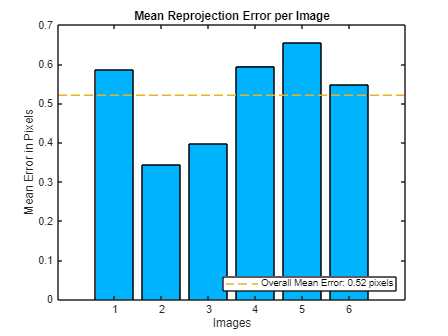

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 15;  % in units of 'centimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'centimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

%obtención de los  intrinsics
intrinsics =cameraParams.Intrinsics;

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

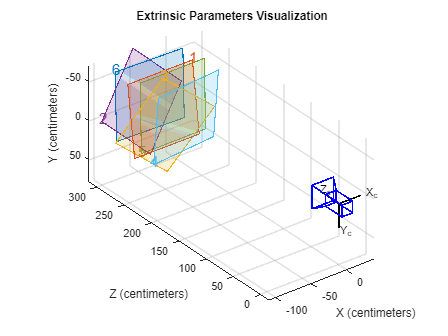

% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');

% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 2767.7397 +/- 20.5490    2766.8066 +/- 20.6512 ]
Principal point (pixels):[ 2138.1060 +/- 4.7988     1202.7421 +/- 3.6433  ]
Radial distortion:       [   -0.0018 +/- 0.0078       -0.0469 +/- 0.0478  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.1063 +/- 0.0017        0.1129 +/- 0.0017        1.5686 +/- 0.0002  ]
                         [   -0.1518 +/- 0.0019       -0.2306 +/- 0.0020       -0.7892 +/- 0.0003  ]
                         [    0.1041 +/- 0.0012        0.0968 +/- 0.0015        0.6984 +/- 0.0002  ]
                         [    0.1466 +/- 0.0018        0.0125 +/- 0.0014       -1.5764 +/- 0.0002  ]
                         [   -0.0079 +/- 0.0018       -0.0150 +/- 0.0019       -1.5719 +/- 0.0002  ]
                         [    0.0046 +/- 0.0013        0.0706 +/- 0.0017       -0.0243 +/- 0.0002  ]




% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
%showdemo('MeasuringPlanarObjectsExample')
%showdemo('StructureFromMotionExample')

videoFilename = "C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7\video1.mp4"; 
reader = VideoReader(videoFilename);

Se extrane un frame del video

frame = readFrame(reader);
frame

frame = 1280×720×3 uint8 array
frame(:,:,1) =

    42    40    34    29    26    26    26    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    28    28    29    29    30    30    31    31    31    31    31    31    31    31    30    30    30    30    30    30    30    30    30    30    30    30    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    29    29    30    29    28    28    28    29    28    28    28    28    28    28    28    29    29    29    29    29    29    29    29    28    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    26    26    26    26    26    26    26    26    25    25    25    25    25    25    25    25    26    27    27    27    27    27    27    27    26    26    26    26    24    24    24    24    23    23    23    23    23    23    23    23    23    23    23    23    23    23    2

Vista de la imagen

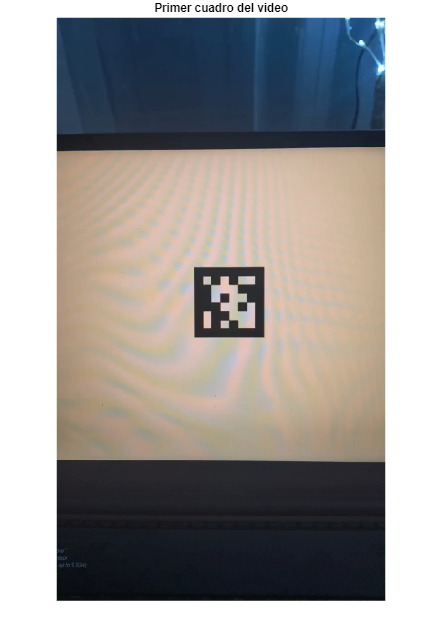

figure;
imshow(frame);
title('Primer cuadro del video');

### Sección 2

 Configurar el marcador AprilTag similar el ejercicio de la tarea 6


tagSize = 27.7813; % Tamaño del marcador en mm
tagFamily = "tag36h11";


Crear un escritor "writer" para guardar el video aumentado 

Yguarda el video para usarlo luego en la salida

outputFilename = 'augmented_video.mp4';
writer = VideoWriter(outputFilename, 'MPEG-4');
open(writer);
writer

writer =   VideoWriter

    General Properties:

       Filename:                 'augmented_video.mp4'
       Path:                     'C:\Users\IZTARU\Desktop\Tefi\Robo\tarea7'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


### Sección 3 

Cliclo para cada fragmennto del video

Apoyo de IA para base con apoyo de documentación de matlab. 

Basado en el código de la tarea 6 de una figura de un prisma de base triangular 

%ciclo por fragmento
while hasFrame(reader)
    % Obtener el iguiente cuadro
    frameActual = readFrame(reader);

    % Marcador AprilTag y datos base
    [id, loc, poseActual] = readAprilTag(frameActual, tagFamily, intrinsics, tagSize);

    if ~isempty(poseActual) % Si se detecta el marcador
        % Ajustes }s en la pose para que el eje Z >= 0
        rotationAngles = [0 180 0];
        tform = rigidtform3d(rotationAngles, [0 0 0]);
        newR = poseActual(1).R * tform.R;
        poseActual(1) = rigidtform3d(newR, poseActual(1).Translation);

        %Tamaño de la figura
        baseSize = tagSize; % Dimensiones de la base 
        height = baseSize / 2; % Altura 
        triangleBaseVertices = [  
                0 height  0;% Vértice 3
                0 height  height;
                -baseSize/2  -baseSize/2 height;% Vértice 2
                -baseSize/2  -baseSize/2 0;% Vértice 2
                baseSize/2  -baseSize/2 0;% Vértice 1
                baseSize/2  -baseSize/2 height;% Vértice 1
                0 height  height;% Vértice 3
                0 height  0;% Vértice 3
                -baseSize/2  -baseSize/2 0;  % Vértice 2
                -baseSize/2  -baseSize/2 height;  % Vértice 2
                baseSize/2  -baseSize/2 height;  % Vértice 1
                baseSize/2  -baseSize/2 0;  % Vértice 1
                0 height  0]% Vértice 3

        % Crea la proyección de  los vértices dek prisma en las coordenadas
        % 2D de la imagen frame base
        projectedVertices = worldToImage(intrinsics, poseActual(1), triangleBaseVertices);

        % Dibujar el triángulo en la imagen
        resultadoFrame = insertShape(frameActual, 'polygon', ...
            reshape(projectedVertices', 1, []), 'Color', 'magenta', 'LineWidth', 5);
    else
        % Si no se detecta un marcador, usar el cuadro original delresultado anterior
        resultadoFrame = frameActual;
    end

    % Escribirel resultado en el video de salida
    writeVideo(writer, resultadoFrame);
end

triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices =          0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907


triangleBaseVertices = 13×3
         0   13.8907         0
         0   13.8907   13.8907
  -13.8907  -13.8907   13.8907
  -13.8907  -13.8907         0
   13.8907  -13.8907         0
   13.8907  -13.8907   13.8907
         0   13.8907   13.8907
         0   13.8907         0
  -13.8907  -13.8907         0
  -13.8907  -13.8907   13.8907



% Cerrar el escritor de video
close(writer);

### Resultado final

Mostraren una ventanita :D en color magenta

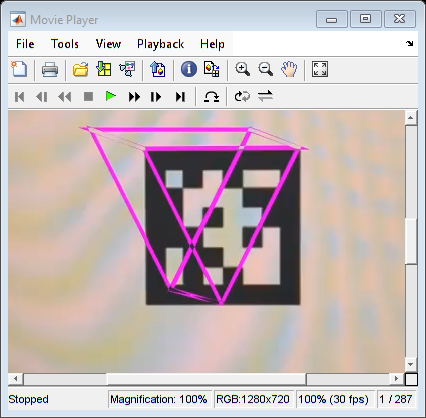

implay(outputFilename);